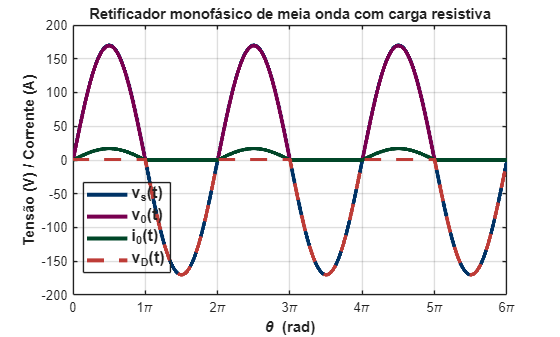

%% Fonte senoidal v_s(t) + retificador de meia-onda (1 diodo) + carga R

clear; clc; close all;

f   = 60;
Vm  = 170;
R   = 10;
Vd  = 0.7;
ncy = 3;
fs  = 200e3;

T = 1/f;
t = 0:1/fs:(ncy*T);

v_s = Vm*sin(2*pi*f*t);
v_0 = max(v_s - Vd, 0);
i_0 = v_0 / R;

v_D = v_s - v_0;

statale.maincolor = [0   51  102]/255;
statale.lilla     = [120 0   80 ]/255;
statale.darkgreen = [0   70  40 ]/255;
statale.red       = [190 60  55 ]/255;
statale.yellow    = [200 155 20 ]/255;

plotColors = [
    statale.maincolor
    statale.lilla
    statale.darkgreen
    statale.red
    statale.yellow
];

set(groot,'defaultAxesColorOrder',plotColors);

LW = 3.0;

theta = 2*pi*f*t;

figure('Color','w');
plot(theta, v_s, 'Color', plotColors(1,:), 'LineWidth', LW); hold on;
plot(theta, v_0, 'Color', plotColors(2,:), 'LineWidth', LW);
plot(theta, i_0, 'Color', plotColors(3,:), 'LineWidth', LW);
plot(theta, v_D, '--', 'Color', plotColors(4,:), 'LineWidth', LW);
grid on;

xlabel('\theta (rad)');
ylabel('Tensão (V) / Corrente (A)');
title('Retificador monofásico de meia onda com carga resistiva');

xlim([0, ncy*2*pi]);
xticks(0:pi:(ncy*2*pi));
xticklabels(compose('%g\\pi', (0:1:(ncy*2))));
xticklabels(strrep(xticklabels,'0\pi','0'));

lgd = legend('v_s(t)','v_0(t)','i_0(t)','v_D(t)','Location','best');
lgd.FontSize   = 12;
lgd.FontWeight = 'bold';
lgd.Color      = 'none';

ax = gca;
ax.XLabel.FontWeight = 'bold';
ax.YLabel.FontWeight = 'bold';